# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.10 甲烷模型

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

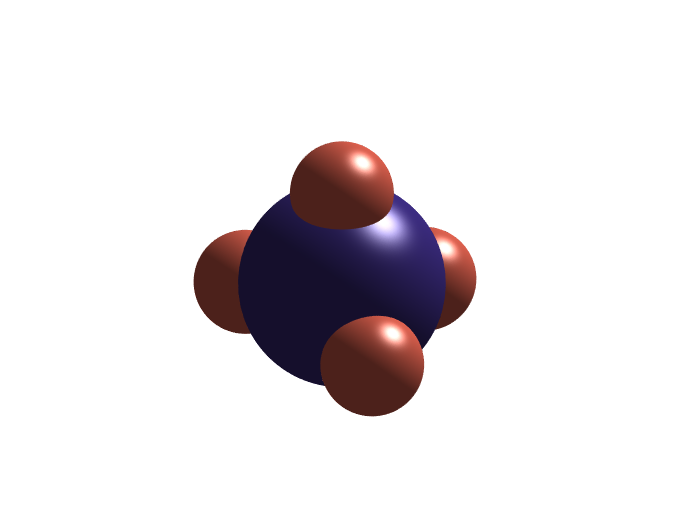

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 球面的坐标信息，为了看起来平滑一点，给到 100
[x, y, z] = sphere(100);
% C 大小
C = 10; 
% H 大小
H = 5;
figure;
% 大球
surf(C*x, C*y, C*z, 'FaceColor', all_colors(6, :), 'EdgeColor', 'none')
hold on 
% 四个小球，都偏离一点位置，准确的位置需要计算，这里演示一个大概位置
surf(H*x, H*y, H*z + 10, 'FaceColor', all_colors(1, :), 'EdgeColor', 'none');
surf(H*x + 10, H*y, H*z - 3, 'FaceColor', all_colors(1, :), 'EdgeColor', 'none');
surf(H*x - 4, H*y - 10, H*z - 3, 'FaceColor', all_colors(1, :), 'EdgeColor', 'none');
surf(H*x - 4, H*y + 10, H*z - 3, 'FaceColor', all_colors(1, :), 'EdgeColor', 'none');
% 坐标轴设置
axis equal off
% 光源，看起来更有立体感
light
lighting gouraud